#     ***Institute of Robotics, University of Innopolis***

# Dynamic of Nonlinear Robotic Systems

# Homework 4

## By Amer Al Badr

October 17,2020

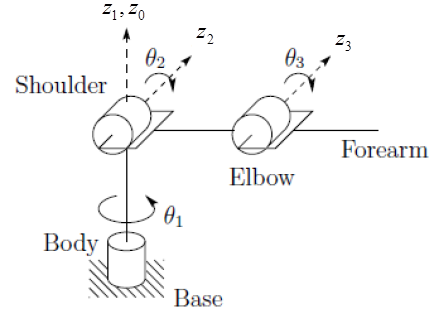

L1=L2=L3=1 m

## DH Parameters and Homogeneous Transform matrices:

We write DH table for this robot as below:

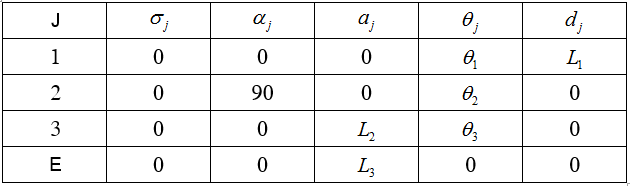

Now we write Homogeneous Transform matrices

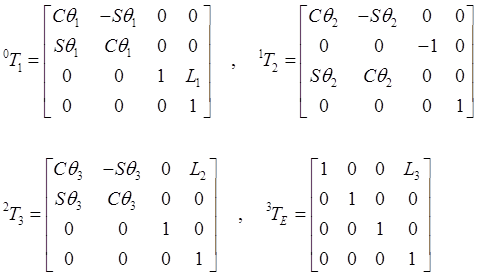

We code the matrices above in aim to get the Forward Kinematics.

syms q1 q2 q3 L1 L2 L3
T01=[cosd(q1) -sind(q1) 0 0;sind(q1) cosd(q1) 0 0;0 0 1 L1;0 0 0 1];
T12=[cosd(q2) -sind(q2) 0 0;0 0 -1 0;sind(q2) cosd(q2) 0 0;0 0 0 1];
T23=[cosd(q3) -sind(q3) 0 L2;sind(q3) cosd(q3) 0 0;0 0 1 0;0 0 0 1];
T3E=[1 0 0 L3;0 1 0 0;0 0 1 0;0 0 0 1];

%FK
T0E=T01*T12*T23*T3E;
simplify(T0E);
display(T0E);

$$\begin{array}{l} \left(\begin{array}{cccc} \sigma_{1}\,\sigma_{4}\,\sigma_{6}-\sigma_{1}\,\sigma_{5}\,\sigma_{7} & -\sigma_{1}\,\sigma_{4}\,\sigma_{7}-\sigma_{1}\,\sigma_{6}\,\sigma_{5} & \sigma_{2} & L_{2}\,\sigma_{1}\,\sigma_{4}-L_{3}\,\left(\sigma_{1}\,\sigma_{5}\,\sigma_{7}-\sigma_{1}\,\sigma_{4}\,\sigma_{6}\right)\\ \sigma_{4}\,\sigma_{6}\,\sigma_{2}-\sigma_{2}\,\sigma_{5}\,\sigma_{7} & -\sigma_{4}\,\sigma_{2}\,\sigma_{7}-\sigma_{6}\,\sigma_{2}\,\sigma_{5} & -\sigma_{1} & L_{2}\,\sigma_{4}\,\sigma_{2}-L_{3}\,\left(\sigma_{2}\,\sigma_{5}\,\sigma_{7}-\sigma_{4}\,\sigma_{6}\,\sigma_{2}\right)\\ \sigma_{3} & \sigma_{4}\,\sigma_{6}-\sigma_{5}\,\sigma_{7} & 0 & L_{1}+L_{2}\,\sigma_{5}+L_{3}\,\sigma_{3}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{3}=\sigma_{4}\,\sigma_{7}+\sigma_{6}\,\sigma_{5}\\ \sigma_{4}=\cos\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{5}=\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{6}=\cos\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{7}=\sin\left(\frac{\pi \,q_{3}}{180}\right) \end{array}$$

So we get FK as:

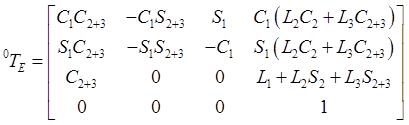

% FK position
Pos_E=T0E*[0 0 0 1]';
display(Pos_E);

$$\begin{array}{l} \left(\begin{array}{c} L_{2}\,\sigma_{4}\,\sigma_{1}-L_{3}\,\left(\sigma_{4}\,\sigma_{2}\,\sigma_{5}-\sigma_{4}\,\sigma_{1}\,\sigma_{3}\right)\\ L_{2}\,\sigma_{1}\,\sigma_{6}-L_{3}\,\left(\sigma_{6}\,\sigma_{2}\,\sigma_{5}-\sigma_{1}\,\sigma_{3}\,\sigma_{6}\right)\\ L_{1}+L_{2}\,\sigma_{2}+L_{3}\,\left(\sigma_{1}\,\sigma_{5}+\sigma_{3}\,\sigma_{2}\right)\\ 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{4}=\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{5}=\sin\left(\frac{\pi \,q_{3}}{180}\right)\\ \sigma_{6}=\sin\left(\frac{\pi \,q_{1}}{180}\right) \end{array}$$

So we get FK position vector as:

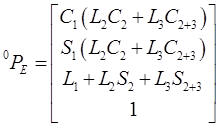

## Calculating Inverse Kinematics

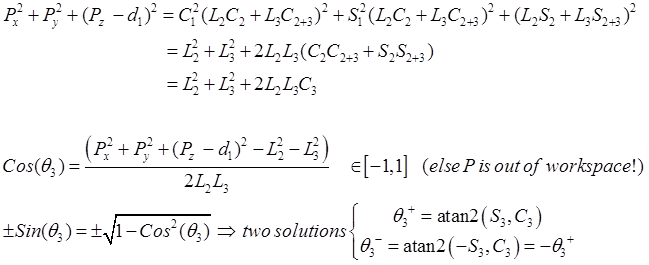

Now we calculate $\theta_1$:

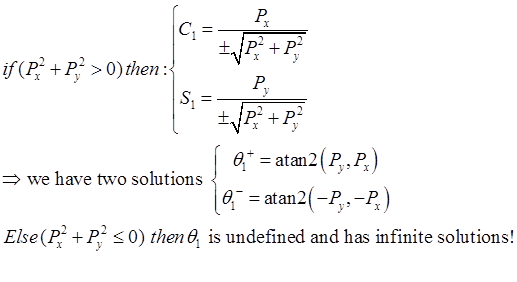

Finally we calculate $\theta_2$:

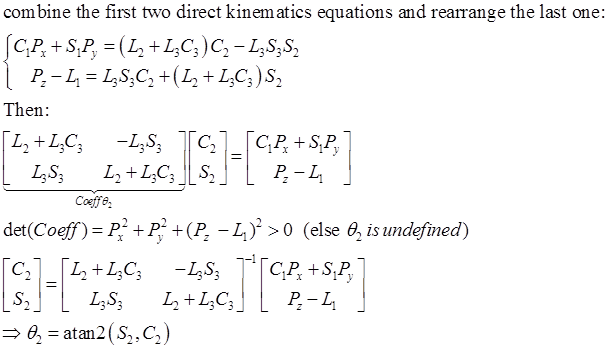

The total number of solutions for the Inverse Kinematics is 2x2x1=4 solutions

## Task one

## Calculate Geometrical Jacobian Matrix

The first three lines of the Geometrical Jacobian matrix can be directly found from deriving the FK position vector  .

The last three lines of  the Geometrical Jacobian matrix can be described as:

-  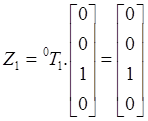

- 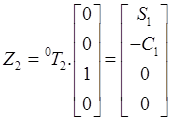

- 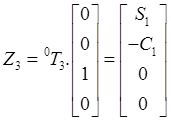 

 Therefore, the Geometrical Jacobian Matrix is:

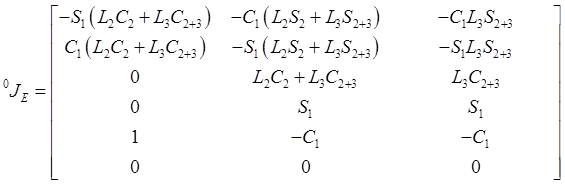

Now we will code the Jacobian matrix:

J=[-sind(q1)*(L2*cosd(q2)+L3*cosd(q2+q3)),-cosd(q1)*(L2*sind(q2)+L3*sind(q2+q3)),-cosd(q1)*L3*sind(q2+q3);
    cos(q1)*(L2*cosd(q2)+L3*cosd(q2+q3)) ,-sind(q1)*(L2*sind(q2)+L3*sind(q2+q3)),-sind(q1)*L3*sind(q2+q3);
                                       0 ,             L2*cosd(q2)+L3*cosd(q2+q3),          L3*cosd(q2+q3);
                                       1 ,                               sind(q1),                sind(q1);
                                       1 ,                              -cosd(q1),               -cosd(q1);
                                       0 ,                                      0,                       0];
disp(J);

$$\begin{array}{l} \left(\begin{array}{ccc} -\sigma_{2}\,\sigma_{1} & -\sigma_{3}\,\sigma_{4} & -L_{3}\,\sigma_{5}\,\sigma_{3}\\ \cos\left(q_{1}\right)\,\sigma_{1} & -\sigma_{2}\,\sigma_{4} & -L_{3}\,\sigma_{5}\,\sigma_{2}\\ 0 & \sigma_{1} & L_{3}\,\cos\left(\frac{\pi \,\left(q_{2}+q_{3}\right)}{180}\right)\\ 1 & \sigma_{2} & \sigma_{2}\\ 1 & -\sigma_{3} & -\sigma_{3}\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{3}\,\cos\left(\frac{\pi \,\left(q_{2}+q_{3}\right)}{180}\right)+L_{2}\,\cos\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{2}=\sin\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{3}=\cos\left(\frac{\pi \,q_{1}}{180}\right)\\ \sigma_{4}=L_{3}\,\sigma_{5}+L_{2}\,\sin\left(\frac{\pi \,q_{2}}{180}\right)\\ \sigma_{5}=\sin\left(\frac{\pi \,\left(q_{2}+q_{3}\right)}{180}\right) \end{array}$$

## Task two

In this task, we will calculate the Joint trajectory q(t) from q(0)=(0,0,0) to q(2)=(2,3,4) with null initial and final velocities and accelerations. (polynomial)

At first, we calculate the Joint trajectory for the first joint:

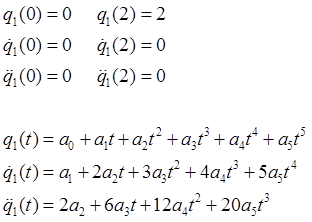

Then we obtain the equation

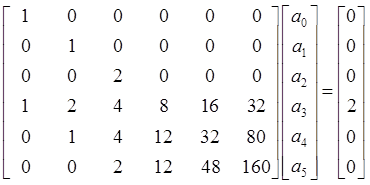

We solve the equation above to get the coefficients of the 5th order polynomial

A1=[1 0 0 0 0 0;0 1 0 0 0 0;0 0 2 0 0 0;1 2 4 8 16 32;0 1 4 12 32 80;0 0 2 12 48 160];
constrain1=[0 0 0 2 0 0]';
Coeff1=inv(A1)*constrain1;
disp(Coeff1);

         0
         0
         0
    2.5000
   -1.8750
    0.3750



As a result we obtain Joint 1 trajectory q1(t) as below:

Now, we apply the same approach to obtain Joint 2 and Joint 3 trajectories q2(t) and q3(t) whose coefficients  follow the equations below:

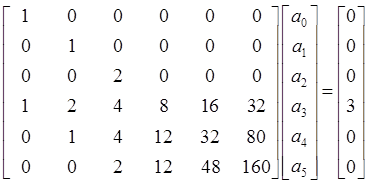  for q2(t) coefficients

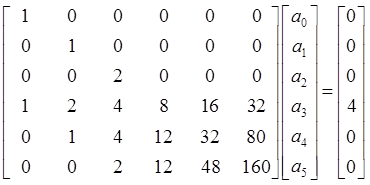for q3(t) coefficients

We calculate the coefficients:

A2=[1 0 0 0 0 0;0 1 0 0 0 0;0 0 2 0 0 0;1 2 4 8 16 32;0 1 4 12 32 80;0 0 2 12 48 160];
constrain2=[0 0 0 3 0 0]';
Coeff2=inv(A2)*constrain2;
disp('q2(t) 5th order polynomial coefficients');

q2(t) 5th order polynomial coefficients


disp(Coeff2);

         0
         0
         0
    3.7500
   -2.8125
    0.5625



A3=[1 0 0 0 0 0;0 1 0 0 0 0;0 0 2 0 0 0;1 2 4 8 16 32;0 1 4 12 32 80;0 0 2 12 48 160];
constrain3=[0 0 0 4 0 0]';
Coeff3=inv(A3)*constrain3;
disp('q3(t) 5th order polynomial coefficients')

q3(t) 5th order polynomial coefficients


disp(Coeff3);

         0
         0
         0
    5.0000
   -3.7500
    0.7500



As a result we obtain the Joint trajectory q(t). (polynomial)

We draw the trajectory:

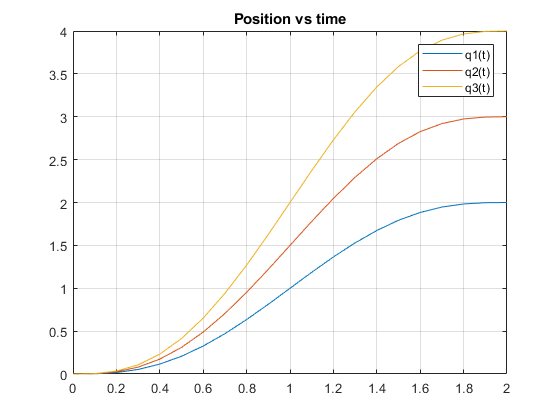

t=0:0.1:2;
q_t=[2.5*t.^3-1.875*t.^4+0.375*t.^5; 3.75*t.^3-2.8125*t.^4+0.5625*t.^5; 5*t.^3-3.75*t.^4+0.75*t.^5];
plot(t,q_t)
title('Position vs time')
grid on
legend ('q1(t)','q2(t)','q3(t)');

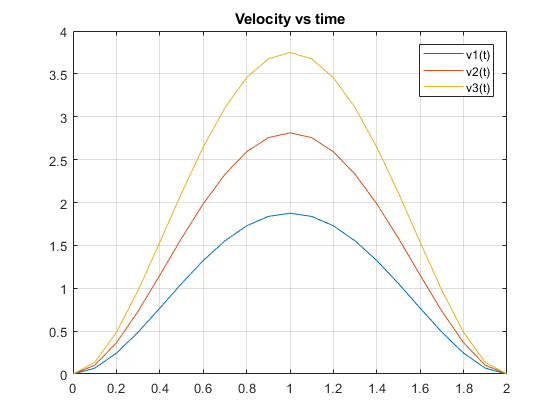

v_t=[2.5*3*t.^2-1.875*4*t.^3+0.375*5*t.^4; 3.75*3*t.^2-2.8125*4*t.^3+0.5625*5*t.^4; 5*3*t.^2-3.75*4*t.^3+0.75*5*t.^4];
plot(t,v_t)
title('Velocity vs time')
grid on
legend ('v1(t)','v2(t)','v3(t)');

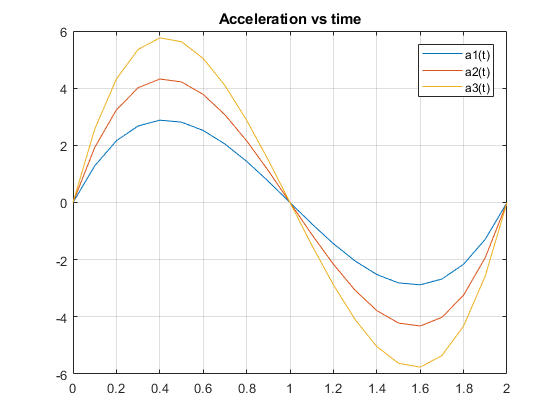

acc_t=[2.5*3*2*t-1.875*4*3*t.^2+0.375*5*4*t.^3; 3.75*3*2*t-2.8125*4*3*t.^2+0.5625*5*4*t.^3; 5*3*2*t-3.75*4*3*t.^2+0.75*5*4*t.^3];
plot(t,acc_t)
title('Acceleration vs time')
grid on
legend ('a1(t)','a2(t)','a3(t)');

## Task three

In this task, we need to calculate a **(trapezoidal Velocity)** Joint trajectory for the following commands: PTP-  q1=(0,0,0) to q2=(2,3,4)

where:

- Controller command interpretation frequency f=100Hz

- Maximum joint velocity 1 rad/s

- Maximum joint acceleration 10 rad/s^2

Thus, the trajectory will be:

where $t_a$and $t_f -t_a$ is the period when the joint moves in constant velocity and they are computed as follows:

In practice, we have the constraint due to the controller frequency ( controller loop time ),this loop time $\Delta t=\frac{1}{f}=0\ldotp 01\text{ }s$ affects the execution time, so we have to adjust the time to be divided by $\Delta t$ with no remainder. and then we need to compute the new actual velocity and acceleration.

q10 = 0; q1f = 2; 
q20 = 0; q2f = 3;
q30 = 0; q3f = 4;
v10 = 0; v20 = 0,v30=0 % initial velocity for the 3 joints

v20 = 0

v30 = 0

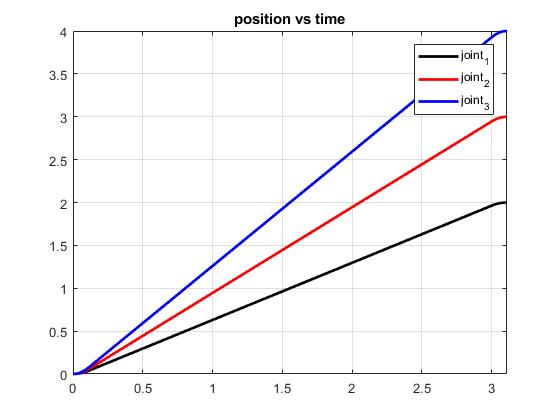

vmax = 1; amax = 10; %Maximum joint velocity and acceleration
f=100; % Controller command interpretation frequency
delta_t = 1/f;
n = 0;
while (floor(delta_t*10^n)~=delta_t*10^n)
    n=n+1;
end
E = 1*10^-n;
ta = vmax/amax;
if rem(ta,delta_t)~=0
    ta_new = round(ta,n)+E;
else
    ta_new = round(ta,n)+E;
end
t1f = (q1f-q10)/vmax + ta_new;
if rem(t1f,delta_t)~=0
    t1f_new = round(t1f,n)+E;
else
    t1f_new = round(t1f,n);
end



t2f = (q2f-q20)/vmax + ta_new;
if rem(t2f,delta_t)~=0
    t2f_new = round(t2f,n)+E;
else
    t2f_new = round(t2f,n);
end


if t2f_new > t1f_new
    tf_new = t2f_new;
    
else
    tf_new = t1f_new;
   
end


v1_new = ((q1f-q10)/(tf_new-ta_new));
a1_new = v1_new/ta_new;

v2_new = ((q2f-q20)/(tf_new-ta_new));
a2_new = v2_new/ta_new;

v3_new = ((q3f-q30)/(tf_new-ta_new));
a3_new = v3_new/ta_new;

% joint 1 - coefficients:
% t0 --> ta:
a10 = q10;
a11 = v10;
a12 = 0.5*a1_new;


% ta --> tf-ta:
a20 = q10 + 0.5*a1_new*ta_new^2 - v1_new*ta_new;
a21 = v1_new;

% tf-ta --> tf:
a30 = q1f - 0.5*a1_new*tf_new^2;
a31 = a1_new*tf_new;
a32 = -0.5*a1_new;

% joint 2 - coefficients:
% t0 --> ta:
b10 = q20;
b11 = v20;
b12 = 0.5*a2_new;


% ta --> tf-ta:
b20 = q20 + 0.5*a2_new*ta_new^2 - v2_new*ta_new;
b21 = v2_new;

% tf-ta --> tf:
b30 = q2f - 0.5*a2_new*tf_new^2;
b31 = a2_new*tf_new;
b32 = -0.5*a2_new;

% joint 3 - coefficients:
% t0 --> ta:
c10 = q30;
c11 = v30;
c12 = 0.5*a3_new;


% ta --> tf-ta:
c20 = q30 + 0.5*a3_new*ta_new^2 - v3_new*ta_new;
c21 = v3_new;

% tf-ta --> tf:
c30 = q3f - 0.5*a3_new*tf_new^2;
c31 = a3_new*tf_new;
c32 = -0.5*a3_new;

t = 0:delta_t:tf_new;
q1 = (a10+a11.*t+a12.*t.^2).*(t<=ta_new)...
    +(a20+a21.*t).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(a30+a31.*t+a32.*t.^2).*(t>(tf_new-ta_new)).*(t<=tf_new);
v1 = (a11+2*a12.*t).*(t<=ta_new)...
    +(a21).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(a31+2*a32.*t).*(t>(tf_new-ta_new)).*(t<=tf_new);
acc1 = (2*a12).*(t<=ta_new)...
    +(0).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(2*a32).*(t>(tf_new-ta_new)).*(t<=tf_new);
q2 = (b10+b11.*t+b12.*t.^2).*(t<=ta_new)...
    +(b20+b21.*t).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(b30+b31.*t+b32.*t.^2).*(t>(tf_new-ta_new)).*(t<=tf_new);
v2 = (b11+2*b12.*t).*(t<=ta_new)...
    +(b21).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(b31+2*b32.*t).*(t>(tf_new-ta_new)).*(t<=tf_new);
acc2 = (2*b12).*(t<=ta_new)...
    +(0).*(t>ta_new).*(t<=(tf_new-ta_new))....
    +(2*b32).*(t>(tf_new-ta_new)).*(t<=tf_new);
q3 = (c10+c11.*t+c12.*t.^2).*(t<=ta_new)...
    +(c20+c21.*t).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(c30+c31.*t+c32.*t.^2).*(t>(tf_new-ta_new)).*(t<=tf_new);
v3 = (c11+2*c12.*t).*(t<=ta_new)...
    +(c21).*(t>ta_new).*(t<=(tf_new-ta_new))...
    +(c31+2*c32.*t).*(t>(tf_new-ta_new)).*(t<=tf_new);
acc3 = (2*c12).*(t<=ta_new)...
    +(0).*(t>ta_new).*(t<=(tf_new-ta_new))....
    +(2*c32).*(t>(tf_new-ta_new)).*(t<=tf_new);

figure
plot(t,q1,'k','linewidth',2)
hold on
plot(t,q2,'r','linewidth',2)
hold on
plot(t,q3,'b','linewidth',2)
grid on
title('position vs time')
legend('joint_1', 'joint_2','joint_3')
axis([0 tf_new -inf inf])

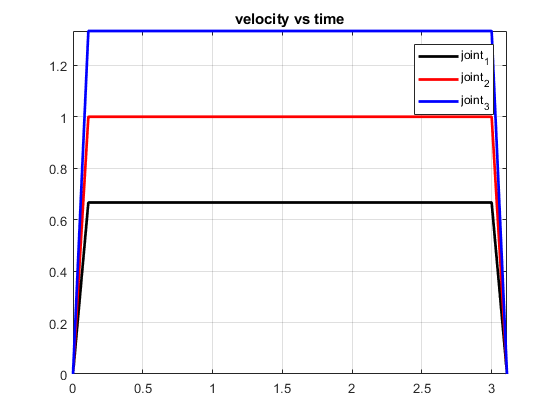

figure
plot(t,v1,'k','linewidth',2)
hold on
plot(t,v2,'r','linewidth',2)
hold on
plot(t,v3,'b','linewidth',2)
title('velocity vs time')
legend('joint_1' , 'joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

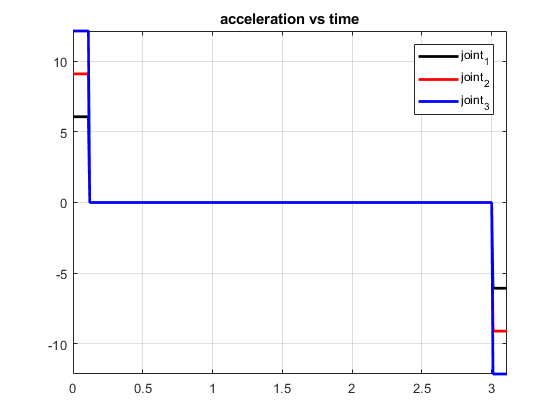

figure
plot(t,acc1,'k','linewidth',2)
hold on
plot(t,acc2,'r','linewidth',2)
hold on
plot(t,acc3,'b','linewidth',2)
title('acceleration vs time')
legend('joint_1','joint_2','joint_3')
grid on
axis([0 tf_new -inf inf])

## Task four

In this task, we compute the Joint trajectory for the following commands: LIN - p1=(1,0,1) to p2($\frac{\sqrt{2}}{2},\frac{\sqrt{2}}{2},1\ldotp 2$). (trapezoidal velocity)

We need to make the robot move in a line as accurate as possible, so at the beginning we define the line with initial and goal positions.

Then we seperate the line into several waypoints (I assumed the number of waypoints to be N=100) and we specify the time at each waypoint.

We calculate the waypoints and the velocities at the waypoints.

After that, we compute the inverse kinematics for each point in aim to get the robot configuration and the Jacobian.

As a result, we obtain a set of configurations and we need to build trajectory between these configurations.

We apply the same procedure in the previous task for each configuration we obtained in the path.

Procedure:

 – Obtain function for task space path

 – Sample function to get discrete points (in task space)

 – Apply IK and Jacobian calculations

 – Fit functions to joints

 – Sample to get discrete reference points (in joint space).

Now, we plan a linear cartesian path  (position only), assuming that the final and initial velocities are zero.

L1=1;L2=1;L3=1;
p1=[0,1,0]; p2=[sqrt(2)/2,sqrt(2)/2,1.2]; % positions
vmax = 1; amax = 10; %Maximum joint velocity and acceleration
f=100; % Controller command interpretation frequency
tf=10;
delta_t = 1/f;
N=100;
tspan = linspace(0,tf,N);
% positions
x = ((p2(1)-p1(1))/tf).*tspan+p1(1);
y = ((p2(2)-p1(2))/tf).*tspan+p1(2);
z = ((p2(3)-p1(3))/tf).*tspan+p1(3);
% velocities
% at t0 and tf: vel=0 for all joints, at waypoints:
% velocities are constant:
vx = ((p2(1)-p1(1))/tf);
vy = ((p2(2)-p1(2))/tf);
vz = ((p2(3)-p1(3))/tf);
vel = [vx;vy;vz];

m1 = 0; % 0 elbow1 up, 1 elbow1 down
m3=  0; % 0 elbow3 up, 1 elbow3 down
for i=1:N
    waypnts = [x(i), y(i), z(i)];
    jointConfig(i,:) =IK(waypnts(1,:),L1,L2,L3,m1,m3);
    if i == 1 || i==N
        jointVel(i,:) = [0 0 0];
    else
        J= Jacobian_Geometrical(jointConfig(i,:),L1,L2,L3)
        jointVel(i,:) =  (J(1:3,:)\vel)';
    end
end

J =    -0.9970    0.0071   -0.0001
   -0.0540    0.9879   -0.0121
         0    0.9971    0.9999
    1.0000    1.0000    1.0000
    1.0000   -0.0072   -0.0072
         0         0         0


J =    -0.9941    0.0140   -0.0003
    0.3490    0.9757   -0.0242
         0    0.9942    0.9997
    1.0000    0.9999    0.9999
    1.0000   -0.0144   -0.0144
         0         0         0


J =    -0.9911    0.0208   -0.0008
    0.6929    0.9634   -0.0363
         0    0.9914    0.9993
    1.0000    0.9998    0.9998
    1.0000   -0.0216   -0.0216
         0         0         0


J =    -0.9882    0.0275   -0.0014
    0.9183    0.9511   -0.0484
         0    0.9886    0.9988
    1.0000    0.9996    0.9996
    1.0000   -0.0289   -0.0289
         0         0         0


J =    -0.9852    0.0340   -0.0022
    0.9850    0.9388   -0.0605
         0    0.9859    0.9982
    1.0000    0.9993    0.9993
    1.0000   -0.0362   -0.0362
         0         0         0


J =    -0.9822    0.0404   -0.0032
    0.8798    0.9264   -0.0726
         0    0.9832    0.9974
    1.0000    0.9990    0.9990
    1.0000   -0.0436   -0.0436
         0         0         0


J =    -0.9793    0.0467   -0.0043
    0.6193    0.9140   -0.0846
         0    0.9806    0.9964
    1.0000    0.9987    0.9987
    1.0000   -0.0510   -0.0510
         0         0         0


J =    -0.9763    0.0528   -0.0057
    0.2484    0.9015   -0.0967
         0    0.9780    0.9953
    1.0000    0.9983    0.9983
    1.0000   -0.0584   -0.0584
         0         0         0


J =    -0.9734    0.0587   -0.0072
   -0.1671    0.8890   -0.1087
         0    0.9755    0.9941
    1.0000    0.9978    0.9978
    1.0000   -0.0659   -0.0659
         0         0         0


J =    -0.9704    0.0645   -0.0089
   -0.5521    0.8764   -0.1207
         0    0.9730    0.9927
    1.0000    0.9973    0.9973
    1.0000   -0.0734   -0.0734
         0         0         0


J =    -0.9675    0.0702   -0.0108
   -0.8354    0.8638   -0.1327
         0    0.9706    0.9911
    1.0000    0.9967    0.9967
    1.0000   -0.0809   -0.0809
         0         0         0


J =    -0.9645    0.0756   -0.0129
   -0.9636    0.8512   -0.1447
         0    0.9683    0.9894
    1.0000    0.9961    0.9961
    1.0000   -0.0885   -0.0885
         0         0         0


J =    -0.9615    0.0810   -0.0151
   -0.9111    0.8385   -0.1566
         0    0.9660    0.9875
    1.0000    0.9954    0.9954
    1.0000   -0.0961   -0.0961
         0         0         0


J =    -0.9586    0.0861   -0.0176
   -0.6863    0.8258   -0.1685
         0    0.9638    0.9855
    1.0000    0.9946    0.9946
    1.0000   -0.1038   -0.1038
         0         0         0


J =    -0.9556    0.0912   -0.0202
   -0.3306    0.8131   -0.1805
         0    0.9616    0.9834
    1.0000    0.9938    0.9938
    1.0000   -0.1114   -0.1114
         0         0         0


J =    -0.9527    0.0960   -0.0231
    0.0887    0.8003   -0.1923
         0    0.9595    0.9811
    1.0000    0.9929    0.9929
    1.0000   -0.1191   -0.1191
         0         0         0


J =    -0.9497    0.1007   -0.0261
    0.4907    0.7875   -0.2042
         0    0.9574    0.9786
    1.0000    0.9919    0.9919
    1.0000   -0.1268   -0.1268
         0         0         0


J =    -0.9467    0.1052   -0.0293
    0.7964    0.7747   -0.2160
         0    0.9554    0.9760
    1.0000    0.9909    0.9909
    1.0000   -0.1346   -0.1346
         0         0         0


J =    -0.9438    0.1095   -0.0328
    0.9447    0.7619   -0.2278
         0    0.9535    0.9732
    1.0000    0.9898    0.9898
    1.0000   -0.1423   -0.1423
         0         0         0


J =    -0.9408    0.1137   -0.0364
    0.9048    0.7490   -0.2395
         0    0.9516    0.9702
    1.0000    0.9887    0.9887
    1.0000   -0.1501   -0.1501
         0         0         0


J =    -0.9379    0.1177   -0.0402
    0.6834    0.7361   -0.2512
         0    0.9498    0.9671
    1.0000    0.9875    0.9875
    1.0000   -0.1579   -0.1579
         0         0         0


J =    -0.9349    0.1215   -0.0442
    0.3238    0.7232   -0.2629
         0    0.9480    0.9638
    1.0000    0.9862    0.9862
    1.0000   -0.1657   -0.1657
         0         0         0


J =    -0.9320    0.1252   -0.0484
   -0.1016    0.7103   -0.2745
         0    0.9463    0.9604
    1.0000    0.9848    0.9848
    1.0000   -0.1736   -0.1736
         0         0         0


J =    -0.9290    0.1287   -0.0528
   -0.5061    0.6973   -0.2860
         0    0.9447    0.9568
    1.0000    0.9834    0.9834
    1.0000   -0.1815   -0.1815
         0         0         0


J =    -0.9260    0.1320   -0.0574
   -0.8059    0.6844   -0.2975
         0    0.9431    0.9530
    1.0000    0.9819    0.9819
    1.0000   -0.1893   -0.1893
         0         0         0


J =    -0.9231    0.1351   -0.0622
   -0.9382    0.6714   -0.3089
         0    0.9416    0.9491
    1.0000    0.9804    0.9804
    1.0000   -0.1972   -0.1972
         0         0         0


J =    -0.9201    0.1380   -0.0671
   -0.8741    0.6584   -0.3203
         0    0.9401    0.9449
    1.0000    0.9787    0.9787
    1.0000   -0.2051   -0.2051
         0         0         0


J =    -0.9172    0.1407   -0.0723
   -0.6260    0.6454   -0.3316
         0    0.9387    0.9406
    1.0000    0.9770    0.9770
    1.0000   -0.2130   -0.2130
         0         0         0


J =    -0.9142    0.1433   -0.0777
   -0.2454    0.6325   -0.3428
         0    0.9374    0.9362
    1.0000    0.9753    0.9753
    1.0000   -0.2210   -0.2210
         0         0         0


J =    -0.9112    0.1457   -0.0832
    0.1873    0.6195   -0.3540
         0    0.9361    0.9315
    1.0000    0.9734    0.9734
    1.0000   -0.2289   -0.2289
         0         0         0


J =    -0.9083    0.1478   -0.0890
    0.5799    0.6065   -0.3650
         0    0.9349    0.9267
    1.0000    0.9715    0.9715
    1.0000   -0.2368   -0.2368
         0         0         0


J =    -0.9053    0.1498   -0.0949
    0.8476    0.5935   -0.3760
         0    0.9337    0.9217
    1.0000    0.9696    0.9696
    1.0000   -0.2448   -0.2448
         0         0         0


J =    -0.9024    0.1516   -0.1011
    0.9320    0.5805   -0.3869
         0    0.9326    0.9166
    1.0000    0.9675    0.9675
    1.0000   -0.2527   -0.2527
         0         0         0


J =    -0.8994    0.1532   -0.1074
    0.8140    0.5676   -0.3977
         0    0.9316    0.9112
    1.0000    0.9654    0.9654
    1.0000   -0.2607   -0.2607
         0         0         0


J =    -0.8965    0.1547   -0.1139
    0.5184    0.5546   -0.4084
         0    0.9307    0.9057
    1.0000    0.9632    0.9632
    1.0000   -0.2686   -0.2686
         0         0         0


J =    -0.8935    0.1559   -0.1206
    0.1093    0.5417   -0.4189
         0    0.9298    0.9000
    1.0000    0.9610    0.9610
    1.0000   -0.2766   -0.2766
         0         0         0


J =    -0.8905    0.1569   -0.1274
   -0.3238    0.5287   -0.4294
         0    0.9289    0.8941
    1.0000    0.9587    0.9587
    1.0000   -0.2845   -0.2845
         0         0         0


J =    -0.8876    0.1577   -0.1345
   -0.6853    0.5158   -0.4397
         0    0.9281    0.8880
    1.0000    0.9563    0.9563
    1.0000   -0.2924   -0.2924
         0         0         0


J =    -0.8846    0.1584   -0.1417
   -0.8951    0.5029   -0.4499
         0    0.9274    0.8818
    1.0000    0.9538    0.9538
    1.0000   -0.3004   -0.3004
         0         0         0


J =    -0.8817    0.1588   -0.1491
   -0.9062    0.4901   -0.4600
         0    0.9268    0.8753
    1.0000    0.9513    0.9513
    1.0000   -0.3083   -0.3083
         0         0         0


J =    -0.8787    0.1590   -0.1566
   -0.7154    0.4772   -0.4699
         0    0.9262    0.8687
    1.0000    0.9487    0.9487
    1.0000   -0.3162   -0.3162
         0         0         0


J =    -0.8757    0.1591   -0.1643
   -0.3650    0.4644   -0.4797
         0    0.9257    0.8619
    1.0000    0.9460    0.9460
    1.0000   -0.3241   -0.3241
         0         0         0


J =    -0.8728    0.1589   -0.1722
    0.0670    0.4516   -0.4893
         0    0.9252    0.8549
    1.0000    0.9433    0.9433
    1.0000   -0.3319   -0.3319
         0         0         0


J =    -0.8698    0.1586   -0.1802
    0.4840    0.4389   -0.4988
         0    0.9249    0.8478
    1.0000    0.9405    0.9405
    1.0000   -0.3398   -0.3398
         0         0         0


J =    -0.8669    0.1580   -0.1884
    0.7923    0.4262   -0.5081
         0    0.9245    0.8404
    1.0000    0.9376    0.9376
    1.0000   -0.3476   -0.3476
         0         0         0


J =    -0.8639    0.1573   -0.1967
    0.9225    0.4135   -0.5173
         0    0.9243    0.8329
    1.0000    0.9347    0.9347
    1.0000   -0.3555   -0.3555
         0         0         0


J =    -0.8609    0.1563   -0.2052
    0.8450    0.4009   -0.5262
         0    0.9241    0.8252
    1.0000    0.9317    0.9317
    1.0000   -0.3633   -0.3633
         0         0         0


J =    -0.8580    0.1552   -0.2138
    0.5773    0.3883   -0.5350
         0    0.9240    0.8174
    1.0000    0.9286    0.9286
    1.0000   -0.3711   -0.3711
         0         0         0


J =    -0.8550    0.1538   -0.2225
    0.1795    0.3758   -0.5436
         0    0.9239    0.8093
    1.0000    0.9255    0.9255
    1.0000   -0.3788   -0.3788
         0         0         0


J =    -0.8521    0.1523   -0.2313
   -0.2588    0.3633   -0.5520
         0    0.9239    0.8011
    1.0000    0.9223    0.9223
    1.0000   -0.3865   -0.3865
         0         0         0


J =    -0.8491    0.1505   -0.2403
   -0.6388    0.3509   -0.5602
         0    0.9240    0.7928
    1.0000    0.9190    0.9190
    1.0000   -0.3942   -0.3942
         0         0         0


J =    -0.8462    0.1486   -0.2494
   -0.8748    0.3385   -0.5682
         0    0.9241    0.7842
    1.0000    0.9157    0.9157
    1.0000   -0.4019   -0.4019
         0         0         0


J =    -0.8432    0.1465   -0.2586
   -0.9138    0.3262   -0.5759
         0    0.9243    0.7755
    1.0000    0.9123    0.9123
    1.0000   -0.4096   -0.4096
         0         0         0


J =    -0.8402    0.1441   -0.2678
   -0.7471    0.3140   -0.5835
         0    0.9245    0.7667
    1.0000    0.9088    0.9088
    1.0000   -0.4172   -0.4172
         0         0         0


J =    -0.8373    0.1416   -0.2772
   -0.4124    0.3018   -0.5908
         0    0.9249    0.7577
    1.0000    0.9053    0.9053
    1.0000   -0.4248   -0.4248
         0         0         0


J =    -0.8343    0.1389   -0.2866
    0.0148    0.2896   -0.5979
         0    0.9252    0.7486
    1.0000    0.9017    0.9017
    1.0000   -0.4323   -0.4323
         0         0         0


J =    -0.8314    0.1359   -0.2962
    0.4388    0.2776   -0.6048
         0    0.9257    0.7393
    1.0000    0.8981    0.8981
    1.0000   -0.4398   -0.4398
         0         0         0


J =    -0.8284    0.1328   -0.3057
    0.7646    0.2656   -0.6114
         0    0.9262    0.7299
    1.0000    0.8944    0.8944
    1.0000   -0.4473   -0.4473
         0         0         0


J =    -0.8254    0.1295   -0.3154
    0.9198    0.2537   -0.6178
         0    0.9268    0.7204
    1.0000    0.8906    0.8906
    1.0000   -0.4547   -0.4547
         0         0         0


J =    -0.8225    0.1260   -0.3251
    0.8702    0.2419   -0.6239
         0    0.9274    0.7107
    1.0000    0.8868    0.8868
    1.0000   -0.4621   -0.4621
         0         0         0


J =    -0.8195    0.1223   -0.3348
    0.6274    0.2301   -0.6298
         0    0.9281    0.7009
    1.0000    0.8830    0.8830
    1.0000   -0.4694   -0.4694
         0         0         0


J =    -0.8166    0.1185   -0.3446
    0.2456    0.2184   -0.6354
         0    0.9289    0.6910
    1.0000    0.8791    0.8791
    1.0000   -0.4767   -0.4767
         0         0         0


J =    -0.8136    0.1144   -0.3544
   -0.1904    0.2068   -0.6408
         0    0.9298    0.6811
    1.0000    0.8751    0.8751
    1.0000   -0.4840   -0.4840
         0         0         0


J =    -0.8107    0.1101   -0.3642
   -0.5846    0.1953   -0.6459
         0    0.9307    0.6710
    1.0000    0.8711    0.8711
    1.0000   -0.4912   -0.4912
         0         0         0


J =    -0.8077    0.1057   -0.3740
   -0.8508    0.1839   -0.6507
         0    0.9316    0.6608
    1.0000    0.8670    0.8670
    1.0000   -0.4983   -0.4983
         0         0         0


J =    -0.8047    0.1011   -0.3838
   -0.9314    0.1726   -0.6553
         0    0.9326    0.6506
    1.0000    0.8629    0.8629
    1.0000   -0.5054   -0.5054
         0         0         0


J =    -0.8018    0.0963   -0.3937
   -0.8097    0.1613   -0.6596
         0    0.9337    0.6403
    1.0000    0.8587    0.8587
    1.0000   -0.5125   -0.5125
         0         0         0


J =    -0.7988    0.0913   -0.4035
   -0.5128    0.1502   -0.6636
         0    0.9349    0.6300
    1.0000    0.8545    0.8545
    1.0000   -0.5195   -0.5195
         0         0         0


J =    -0.7959    0.0862   -0.4133
   -0.1055    0.1391   -0.6674
         0    0.9361    0.6196
    1.0000    0.8502    0.8502
    1.0000   -0.5265   -0.5265
         0         0         0


J =    -0.7929    0.0808   -0.4230
    0.3244    0.1282   -0.6708
         0    0.9374    0.6091
    1.0000    0.8459    0.8459
    1.0000   -0.5334   -0.5334
         0         0         0


J =    -0.7899    0.0753   -0.4327
    0.6854    0.1173   -0.6741
         0    0.9387    0.5987
    1.0000    0.8415    0.8415
    1.0000   -0.5402   -0.5402
         0         0         0


J =    -0.7870    0.0696   -0.4424
    0.9012    0.1065   -0.6770
         0    0.9401    0.5882
    1.0000    0.8371    0.8371
    1.0000   -0.5470   -0.5470
         0         0         0


J =    -0.7840    0.0638   -0.4520
    0.9274    0.0959   -0.6797
         0    0.9416    0.5777
    1.0000    0.8327    0.8327
    1.0000   -0.5538   -0.5538
         0         0         0


J =    -0.7811    0.0577   -0.4616
    0.7595    0.0853   -0.6821
         0    0.9431    0.5672
    1.0000    0.8282    0.8282
    1.0000   -0.5604   -0.5604
         0         0         0


J =    -0.7781    0.0516   -0.4711
    0.4336    0.0749   -0.6843
         0    0.9447    0.5567
    1.0000    0.8237    0.8237
    1.0000   -0.5671   -0.5671
         0         0         0


J =    -0.7752    0.0452   -0.4805
    0.0180    0.0645   -0.6862
         0    0.9463    0.5462
    1.0000    0.8191    0.8191
    1.0000   -0.5736   -0.5736
         0         0         0


J =    -0.7722    0.0387   -0.4898
   -0.4013    0.0543   -0.6878
         0    0.9480    0.5357
    1.0000    0.8145    0.8145
    1.0000   -0.5801   -0.5801
         0         0         0


J =    -0.7692    0.0320   -0.4991
   -0.7390    0.0442   -0.6891
         0    0.9498    0.5253
    1.0000    0.8099    0.8099
    1.0000   -0.5866   -0.5866
         0         0         0


J =    -0.7663    0.0252   -0.5083
   -0.9273    0.0342   -0.6903
         0    0.9516    0.5150
    1.0000    0.8052    0.8052
    1.0000   -0.5929   -0.5929
         0         0         0


J =    -0.7633    0.0182   -0.5174
   -0.9295    0.0243   -0.6911
         0    0.9535    0.5047
    1.0000    0.8005    0.8005
    1.0000   -0.5993   -0.5993
         0         0         0


J =    -0.7604    0.0110   -0.5263
   -0.7466    0.0145   -0.6917
         0    0.9554    0.4944
    1.0000    0.7958    0.7958
    1.0000   -0.6055   -0.6055
         0         0         0


J =    -0.7574    0.0037   -0.5352
   -0.4161    0.0048   -0.6921
         0    0.9574    0.4843
    1.0000    0.7911    0.7911
    1.0000   -0.6117   -0.6117
         0         0         0


J =    -0.7544   -0.0037   -0.5440
   -0.0040   -0.0048   -0.6923
         0    0.9595    0.4742
    1.0000    0.7863    0.7863
    1.0000   -0.6179   -0.6179
         0         0         0


J =    -0.7515   -0.0113   -0.5526
    0.4091   -0.0142   -0.6922
         0    0.9616    0.4642
    1.0000    0.7815    0.7815
    1.0000   -0.6239   -0.6239
         0         0         0


J =    -0.7485   -0.0191   -0.5612
    0.7434   -0.0235   -0.6919
         0    0.9638    0.4544
    1.0000    0.7767    0.7767
    1.0000   -0.6299   -0.6299
         0         0         0


J =    -0.7456   -0.0270   -0.5696
    0.9359   -0.0327   -0.6913
         0    0.9660    0.4446
    1.0000    0.7718    0.7718
    1.0000   -0.6359   -0.6359
         0         0         0


J =    -0.7426   -0.0350   -0.5779
    0.9514   -0.0418   -0.6906
         0    0.9683    0.4350
    1.0000    0.7669    0.7669
    1.0000   -0.6417   -0.6417
         0         0         0


J =    -0.7397   -0.0432   -0.5860
    0.7885   -0.0508   -0.6896
         0    0.9706    0.4255
    1.0000    0.7620    0.7620
    1.0000   -0.6476   -0.6476
         0         0         0


J =    -0.7367   -0.0515   -0.5941
    0.4791   -0.0597   -0.6885
         0    0.9730    0.4161
    1.0000    0.7571    0.7571
    1.0000   -0.6533   -0.6533
         0         0         0


J =    -0.7337   -0.0599   -0.6020
    0.0815   -0.0684   -0.6871
         0    0.9755    0.4069
    1.0000    0.7522    0.7522
    1.0000   -0.6590   -0.6590
         0         0         0


J =    -0.7308   -0.0685   -0.6097
   -0.3310   -0.0770   -0.6856
         0    0.9780    0.3978
    1.0000    0.7472    0.7472
    1.0000   -0.6646   -0.6646
         0         0         0


J =    -0.7278   -0.0772   -0.6174
   -0.6840   -0.0855   -0.6838
         0    0.9806    0.3889
    1.0000    0.7422    0.7422
    1.0000   -0.6701   -0.6701
         0         0         0


J =    -0.7249   -0.0860   -0.6249
   -0.9151   -0.0938   -0.6819
         0    0.9832    0.3801
    1.0000    0.7373    0.7373
    1.0000   -0.6756   -0.6756
         0         0         0


J =    -0.7219   -0.0949   -0.6323
   -0.9847   -0.1021   -0.6798
         0    0.9859    0.3715
    1.0000    0.7323    0.7323
    1.0000   -0.6810   -0.6810
         0         0         0


J =    -0.7189   -0.1040   -0.6395
   -0.8824   -0.1102   -0.6776
         0    0.9886    0.3631
    1.0000    0.7272    0.7272
    1.0000   -0.6864   -0.6864
         0         0         0


J =    -0.7160   -0.1132   -0.6466
   -0.6275   -0.1182   -0.6752
         0    0.9914    0.3549
    1.0000    0.7222    0.7222
    1.0000   -0.6917   -0.6917
         0         0         0


J =    -0.7130   -0.1225   -0.6536
   -0.2654   -0.1261   -0.6727
         0    0.9942    0.3468
    1.0000    0.7172    0.7172
    1.0000   -0.6969   -0.6969
         0         0         0


J =    -0.7101   -0.1319   -0.6605
    0.1418   -0.1338   -0.6700
         0    0.9971    0.3390
    1.0000    0.7122    0.7122
    1.0000   -0.7020   -0.7020
         0         0         0



% for each joint:
n = 20;
Q = [];
Qd = [];
Qdd=[];
for i=1:N-1
    t1 = tspan(i); t2 = tspan(i+1);
   
    for j = 1:3
         q10 = jointConfig(i,j); q1f = jointConfig(i+1,j);
         v10 = jointVel(i,1); v1f = jointVel(i+1,j);
         n = 0;
while (floor(delta_t*10^n)~=delta_t*10^n)
    n=n+1;
end
E = 1*10^-n;
ta = vmax/amax;
if rem(ta,delta_t)~=0
    ta_new = round(ta,n)+E;
else
    ta_new = round(ta,n)+E;
end
t1f = (q1f-q10)/vmax + ta_new;
if rem(t1f,delta_t)~=0
    t1f_new = round(t1f,n)+E;
else
    t1f_new = round(t1f,n);
end
v1_new = ((q1f-q10)/(t1f_new-ta_new));
a1_new = v1_new/ta_new;

% joint j - coefficients:
% t0 --> ta:
a10 = q10;
a11 = v10;
a12 = 0.5*a1_new;


% ta --> tf-ta:
a20 = q10 + 0.5*a1_new*ta_new^2 - v1_new*ta_new;
a21 = v1_new;

% tf-ta --> tf:
a30 = q1f - 0.5*a1_new*t1f_new^2;
a31 = a1_new*t1f_new;
a32 = -0.5*a1_new;

tt = 0:delta_t:t1f_new;
sq = (a10+a11.*tt+a12.*tt.^2).*(tt<=ta_new)...
    +(a20+a21.*tt).*(tt>ta_new).*(tt<=(t1f_new-ta_new))...
    +(a30+a31.*tt+a32.*tt.^2).*(tt>(t1f_new-ta_new)).*(tt<=t1f_new);
q_n(j,1:length(sq))=sq;
sqd = (a11+2*a12.*tt).*(tt<=ta_new)...
    +(a21).*(tt>ta_new).*(tt<=(t1f_new-ta_new))...
    +(a31+2*a32.*tt).*(tt>(t1f_new-ta_new)).*(tt<=t1f_new);
qd_n(j,1:length(sqd))=sqd;
sqdd = (2*a12).*(tt<=ta_new)...
    +(0).*(tt>ta_new).*(tt<=(t1f_new-ta_new))...
    +(2*a32).*(tt>(t1f_new-ta_new)).*(tt<=t1f_new);
qdd_n(j,1:length(sqdd))=sqdd;
        
         

    end   
    Q = [Q q_n];
    Qd = [Qd qd_n];
    Qdd=[Qdd qdd_n]
end 

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

Qdd =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958    8.9958         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

qq=[Q(1,:),Q(2,:),Q(3,:)];
cartTraj =FK(qq,L1,L2,L3);

l1 = L1; l2 = L2; l3 = L3;
q1 = jointConfig(1,1);
q2 = jointConfig(1,2);
q3 = jointConfig(1,3);



Plot the joints configuration and the desired vs actual graph

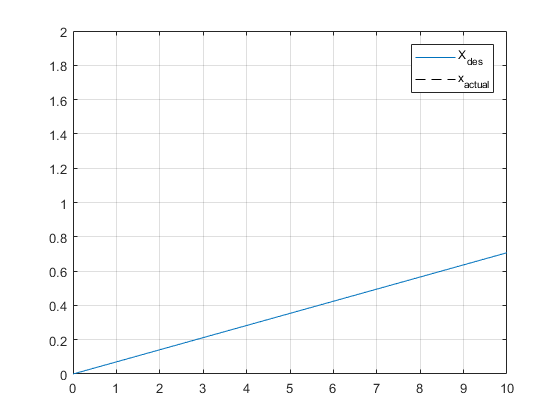

ns = n*N-n;
figure
plot(tspan, x )
hold on 
T = linspace(0,tf,ns);
plot(T,cartTraj(1,:),'k--')
grid on
legend('X_{des}','x_{actual}')

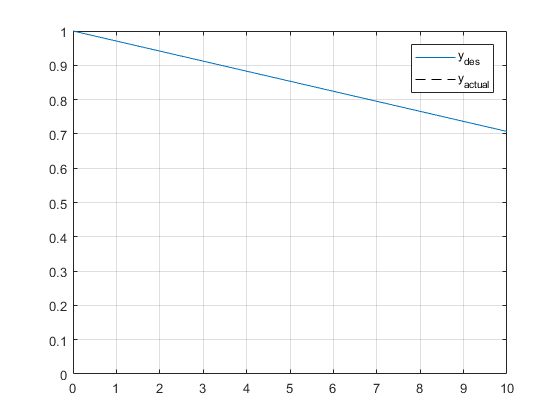

figure
plot(tspan, y )
hold on 
T = linspace(0,tf,ns);
plot(T,cartTraj(2,:),'k--')
grid on
legend('y_{des}','y_{actual}')

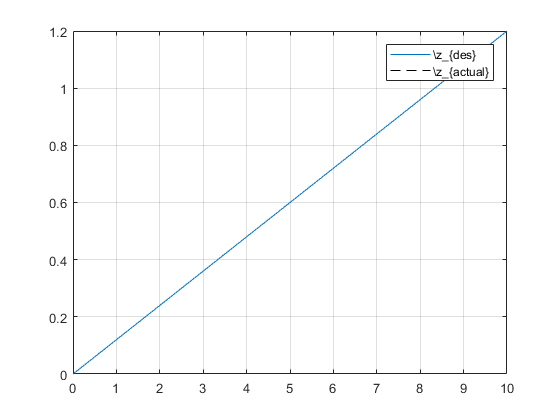

figure
plot(tspan, z )
hold on 
T = linspace(0,tf,ns);
plot(T,cartTraj(3,:),'k--')
grid on
legend('\z_{des}','\z_{actual}')

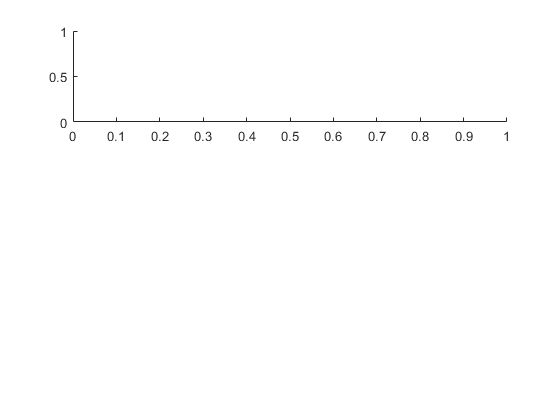

figure
subplot(311)

plot(T, Q(1,:))

Error using plot
Vectors must be the same length.

ylabel('joint 1')
grid on
subplot(312)
plot(T, Q(2,:))
ylabel('joint 2')
grid on
subplot(313)
plot(T, Q(3,:))
ylabel('joint 3')
grid on



